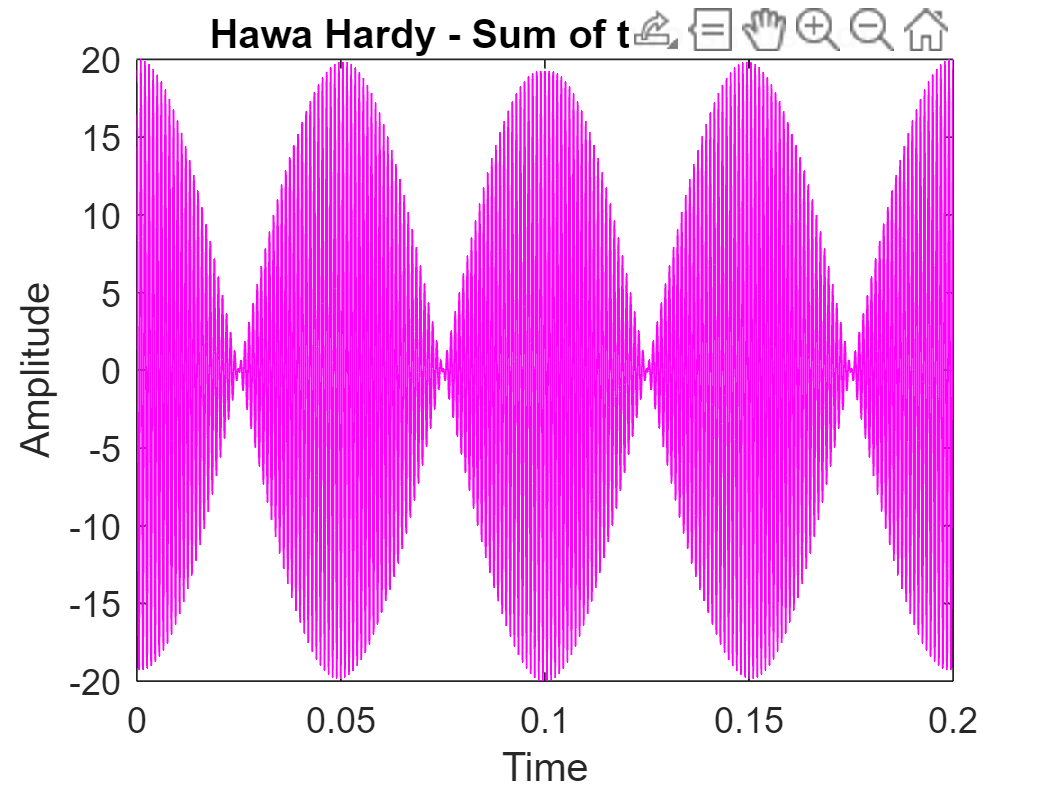

%Compute samples of sum of the two cosine waves.
%A = Amplitude of the lower frequency cosine
%B = Amplitude of higher frequency cosine
%fc = center frequency
%delf = frequency difference
%fsamp = sampling frequency
%dur = total time duration in seconds
%xx = outputs vector of samples
% == second output
%tt == time vector of samples

A = 10;
B = 10; fc = 1000;
delf = 10;
fsamp = 11025;
dur = 1;
[xx, tt] = beat(A, B, fc, delf, fsamp, dur);
%soundsc(xx, fsamp);
dur = 0.2;
[xx, tt] = beat(A, B, fc, delf, fsamp, dur);
plot(tt, xx, 'm');
title('Hawa Hardy - Sum of two sinusoids');
xlabel('Time');
ylabel('Amplitude');

clear sound

%------------------------
% MATLAB code for plotting with period measurements
figure;
plot(tt, xx, 'm');
title('Envelope with measurements');
xlabel('Time (s)');
ylabel('Amplitude');
hold on;

% Plot envelope period
envelope_period = 1 / (2 * delf);
plot([0 envelope_period], [20 20], 'k--', 'LineWidth', 2);

% Plot high-frequency period
high_freq_period = 1 / delf;
plot([0 high_freq_period], [0 0], 'y--', 'LineWidth', 2);

legend('Sinusoid signal', 'Envelope period', 'High-frequency period');
grid on;